clc;
clear;
close all;

% Define system parameters
C1 = 100; % Heat capacity of room 1 (J/K)
C2 = 150; % Heat capacity of room 2 (J/K)
h = 0.05; % Heat transfer coefficient btw room and outside temp (W/K.m^2)
A_s = 20; % Surface area of room 1 (m^2)
A_s2 = 40; % Surface area of room 2 (m^2)
k = 0.7; % Heat transfer coefficient btw the rooms(W/K.m^2)
Tout = 20; % Outside temperature (degC)

%System State Space Representation
A = [-(h*A_s+k)/C1, k/C1;
    k/C2, -(h*A_s2+k)/C2];
B = [1/C1 0; 0, 1/C2];
C = [1 0; 0 1];
D = 0*eye(2);

%State Space Representation
sysSS = ss(A,B,C,D);

%define the desired state
T_d = [100; 150]; % Desired temperature of each room (degC)

% compute ud
% ud = -inv(B'*B)*B'*A*T_d;
ud = -B^-1*A*T_d; % B is invertible so you don't need pseudoinverse

%% simulate the system response for the computed ud
 
% set initial condition
x0=[0;0];
t=0:1:800;
input_ud=ud*ones(size(t));

[~,~,x_base] = lsim(sysSS,input_ud,t,x0); 

## simulate the LQR algorithm

close all;
q = 20;
Q= q*eye(2);
R= 1*eye(2);

[K,~,~] = lqr(sysSS,Q,R);

%simulate the closed loop system 
% closed loop matrix 
Acl= A-B*K;
Bcl=-Acl;
C=[1 0; 0 1];
D=0*eye(2);
sys_cl=ss(Acl,Bcl,C,D);
 
u_cl = [T_d(1)*ones(size(t));
       T_d(2)*ones(size(t))];

[y_cl,t_cl,x_cl] = lsim(sys_cl,u_cl,t,x0); 

% Plot
figure(1)
plot(t,x_base(:,1),'b--'); hold on

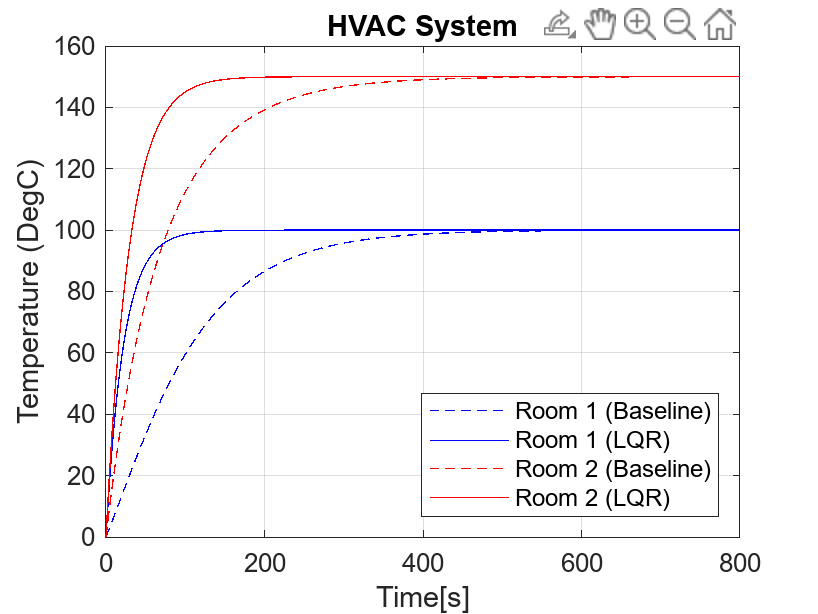

plot(t_cl,x_cl(:,1),'b')
plot(t,x_base(:,2),'r--')
plot(t_cl,x_cl(:,2),'r')

xlabel('Time[s]')
ylabel('Temperature (DegC)')
title('HVAC System')
legend('Room 1 (Baseline)','Room 1 (LQR)', ...
    'Room 2 (Baseline)', 'Room 2 (LQR)', ...
    'Location', 'southeast')
ylim([0 160])
grid
hold off;